# **Assignment 2 - Wheel Odometry**

**Name**: Sugumar Prabhakaran (id#: 994126815)

**Course**: ROB521 - Mobile Robotics

**Instructor**: Dr. Steven Waslander

**Due Date**: 23 Mar 2022

## Results and Analysis

### Question 1 - Implement (Noise-Free) Wheel Odometry Algorithm 

In figure 1 (subplot *top-left *and *top-right*), the odometry data (red) is plotted in comparison with the ground-truth data (blue).  In order to obtain the robot pose estimate [x, y, θ] from the odometry data, I integrated the given angular velocity (ω) and translational velocity (v) over each discrete time-step (∆t). 

The result from the top two subplots is that the position [x,y] and orientation/heading [θ] very closely match the ground truth.  From the bottom two sub-plots, we see that the respective errors are very small.  Since random noise is not a possible source of error, in this task, any error must be attributed to issues with the sensors/sensor data.

**Figure 1**

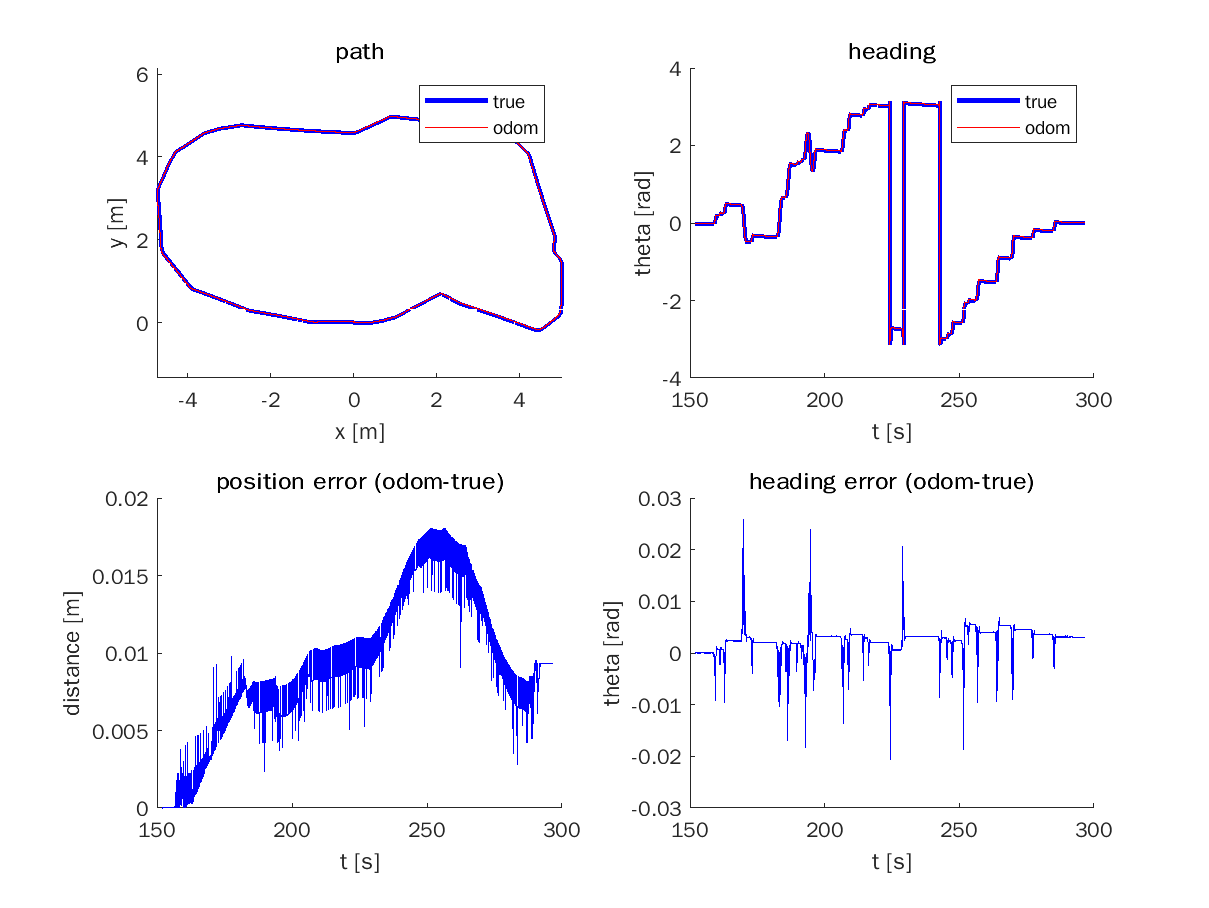

### Question 2 - Implement Odometry Algorithm with Noise

For this task, we added a noise term to the velocity and angular velocity that are both normally distributed using the MATLAB randn() function.  This generates random terms with a mean of zero and standard deviation of 1, which was then scaled by constant factors 0.2 and 0.04 respectively.  

In figure 2, 100 iterations of the algorithm were plotted, which clearly show that the error accumulates as a result of the random noise.  Further, we can see that this is roughly normally distributed around the true-path, where there is a higher concentration of paths.

**Figure 2                                                                                      Figure 3**

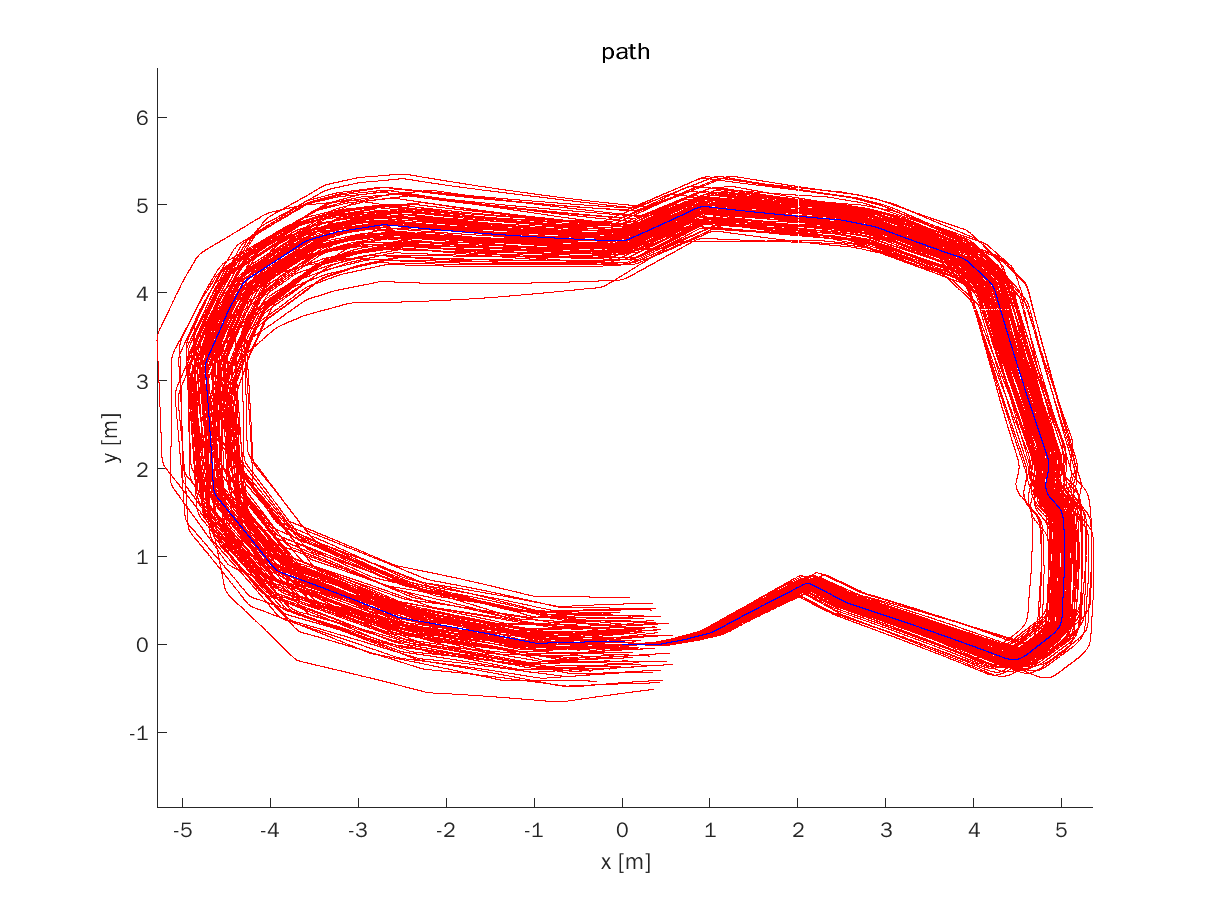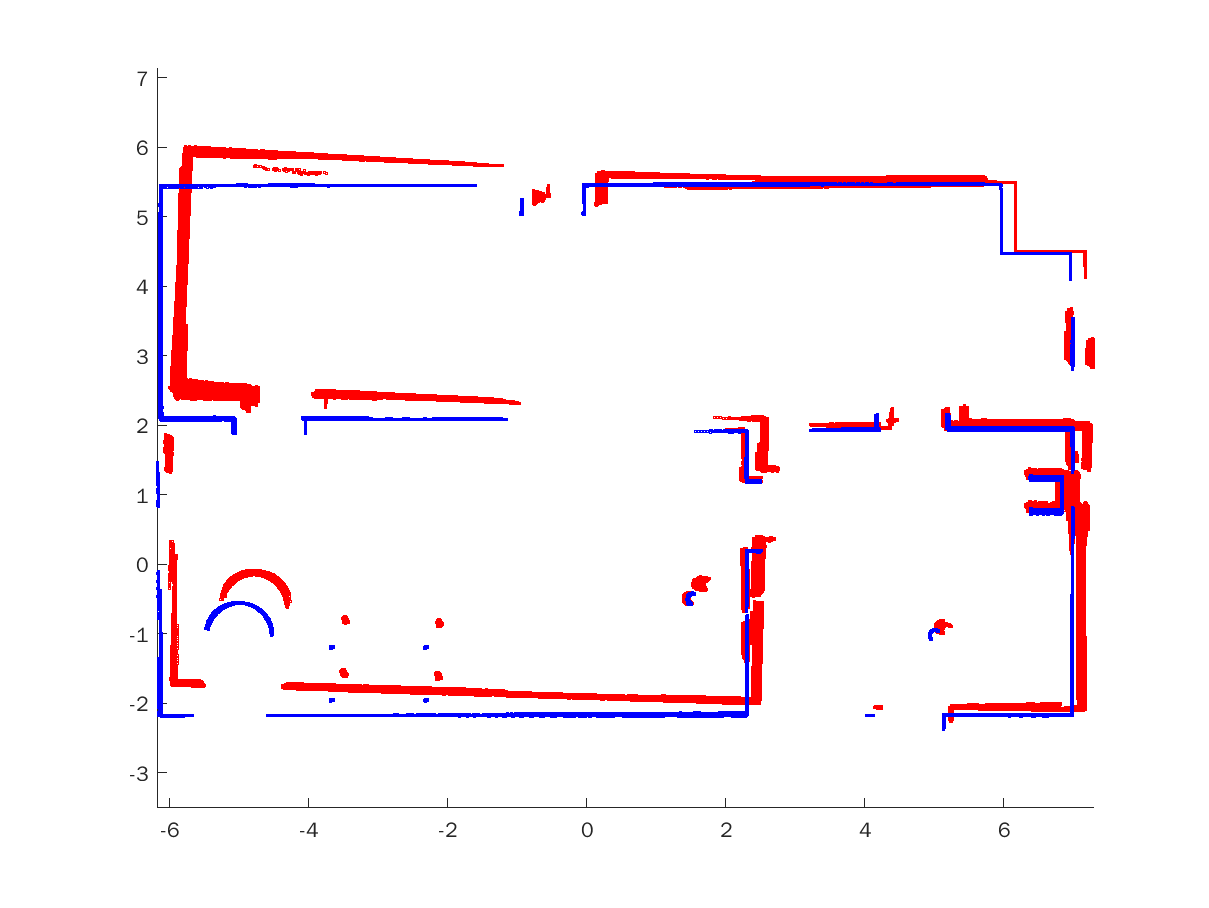

### Question 3 - Build Map Using Laser Scan Data from Ground Truth and Noisy Wheel Odometry

Finally, using laser scan data, we constructed a map of the surroundings by transforming the laser data points first into the robot frame and then transforming them into the inertial frame with origin at [0,0] on figure 3 (above).  

To transform from the robot frame to the inertial frame, we need the current pose estimate of the robot [x, y, θ] at that paticular time of the laser scan, which is calculated in the previous step using the odometry algorithm. The same process was first done for the last laser scan data from the last iteration of the noisy-odometry (red) and then again using the ground-truth (noise-free data), depicted in blue.  We can see from figure 3, that as the vehicle moves in a counter-clockwise direction from the bottom right room, the odometry noise errors accumulate.

## Appendix - Source Code

% ======
% ROB521_assignment2.m
% ======
%
% This assignment will introduce you to the idea of estimating the motion 
% of a mobile robot using wheel odometry, and then also using that wheel
% odometry to make a simple map.  It uses a dataset previously gathered in
% a mobile robot simulation environment called Gazebo. Watch the video,
% 'gazebo.mp4' to visualize what the robot did, what its environment
% looks like, and what its sensor stream looks like.
% 
% There are three questions to complete (5 marks each):
%
%    Question 1: code (noise-free) wheel odometry algorithm
%    Question 2: add noise to data and re-run wheel odometry algorithm
%    Question 3: build a map from ground truth and noisy wheel odometry
%
% Fill in the required sections of this script with your code, run it to
% generate the requested plots, then paste the plots into a short report
% that includes a few comments about what you've observed.  Append your
% version of this script to the report.  Hand in the report as a PDF file.
%
% requires: basic Matlab, 'ROB521_assignment2_gazebo_data.mat'
%
% T D Barfoot, December 2015
%
clear;

% set random seed for repeatability
rng(1);

% ==========================
% load the dataset from file
% ==========================
%
%    ground truth poses: t_true x_true y_true theta_true
% odometry measurements: t_odom v_odom omega_odom
%           laser scans: t_laser y_laser
%    laser range limits: r_min_laser r_max_laser
%    laser angle limits: phi_min_laser phi_max_laser
%
load ROB521_assignment2_gazebo_data.mat;

%% 
% ======================================================
% Question 1: code (noise-free) wheel odometry algorithm
% ======================================================
%
% Write an algorithm to estimate the pose of the robot throughout motion
% using the wheel odometry data (t_odom, v_odom, omega_odom) and assuming
% a differential-drive robot model.  Save your estimate in the variables
% (x_odom y_odom theta_odom) so that the comparison plots can be generated
% below.  See the plot 'ass1_q1_soln.png' for what your results should look
% like.

% variables to store wheel odometry pose estimates
numodom = size(t_odom,1);
x_odom = zeros(numodom,1);
y_odom = zeros(numodom,1);
theta_odom = zeros(numodom,1);

% set the initial wheel odometry pose to ground truth
x_odom(1) = x_true(1);
y_odom(1) = y_true(1);
theta_odom(1) = theta_true(1);

% ------insert your wheel odometry algorithm here-------

for i=2:numodom

% from notes:
% q_bar(t+h) = q_bar(t) + R*[v(t) omega(t)]^T
    delta_t = t_odom(i)-t_odom(i-1);
    x_odom(i) = x_odom(i-1) + [cos(theta_odom(i-1)), 0]*...
               [v_odom(i-1); omega_odom(i-1)]*delta_t;
    y_odom(i) = y_odom(i-1) + [sin(theta_odom(i-1)), 0]*...
               [v_odom(i-1); omega_odom(i-1)]*delta_t;
    theta_odom(i) = theta_odom(i-1) +omega_odom(i-1)*delta_t;

end

% normalize theta angles between pi and -pi
theta_odom = wrapToPi(theta_odom);

% ------end of your wheel odometry algorithm-------

% plot the results for verification
figure(1)
clf;

subplot(2,2,1);
hold on;
plot(x_true,y_true,'b', 'LineWidth',2);
plot(x_odom, y_odom, 'r');
legend('true', 'odom');
xlabel('x [m]');
ylabel('y [m]');
title('path');
axis equal;

subplot(2,2,2);
hold on;
plot(t_true,theta_true,'b','LineWidth',2);
plot(t_odom,theta_odom,'r');
legend('true', 'odom');
xlabel('t [s]');
ylabel('theta [rad]');
title('heading');

subplot(2,2,3);
hold on;
pos_err = zeros(numodom,1);
for i=1:numodom
    pos_err(i) = sqrt((x_odom(i)-x_true(i))^2 + (y_odom(i)-y_true(i))^2);
end
plot(t_odom,pos_err,'b');
xlabel('t [s]');
ylabel('distance [m]');
title('position error (odom-true)');

subplot(2,2,4);
hold on;
theta_err = zeros(numodom,1);
for i=1:numodom
    phi = theta_odom(i) - theta_true(i);
    while phi > pi
        phi = phi - 2*pi;
    end
    while phi < -pi
        phi = phi + 2*pi;
    end 
    theta_err(i) = phi;
end
plot(t_odom,theta_err,'b');
xlabel('t [s]');
ylabel('theta [rad]');
title('heading error (odom-true)');
print -dpng ass1_q1.png


%% 
% =================================================================
% Question 2: add noise to data and re-run wheel odometry algorithm
% =================================================================
%
% Now we're going to deliberately add some noise to the linear and 
% angular velocities to simulate what real wheel odometry is like.  Copy
% your wheel odometry algorithm from above into the indicated place below
% to see what this does.  The below loops 100 times with different random
% noise.  See the plot 'ass1_q2_soln.pdf' for what your results should look
% like.

% save the original odometry variables for later use
v_odom_noisefree = v_odom;
omega_odom_noisefree = omega_odom;

% set up plot
figure(2);
clf;
hold on;

% loop over random trials
for n=1:100
    
    % add noise to wheel odometry measurements (on purpose to see effect)
    v_odom = v_odom_noisefree + 0.2*randn(numodom,1);
    omega_odom = omega_odom_noisefree + 0.04*randn(numodom,1);
    
    % ------insert your wheel odometry algorithm here-------
    for i=2:numodom

        % from notes:
        % q_bar(t+h) = q_bar(t) + R*[v(t) omega(t)]^T
        delta_t = t_odom(i)-t_odom(i-1);
        x_odom(i) = x_odom(i-1) + [cos(theta_odom(i-1)), 0]*...
                   [v_odom(i-1); omega_odom(i-1)]*delta_t;
        y_odom(i) = y_odom(i-1) + [sin(theta_odom(i-1)), 0]*...
                   [v_odom(i-1); omega_odom(i-1)]*delta_t;
        theta_odom(i) = theta_odom(i-1) +omega_odom(i-1)*delta_t;    
    end

    % ------end of your wheel odometry algorithm------- 
    
    % add the results to the plot
    plot(x_odom, y_odom, 'r');
end

% plot ground truth on top and label
plot(x_true,y_true,'b');
xlabel('x [m]');
ylabel('y [m]');
title('path');
axis equal;
print -dpng ass1_q2.png


%% 
% ================================================================
% Question 3: build a map from noisy and noise-free wheel odometry
% ================================================================
%
% Now we're going to try to plot all the points from our laser scans in the
% robot's initial reference frame.  This will involve first figuring out
% how to plot the points in the current frame, then transforming them back
% to the initial frame and plotting them.  Do this for both the ground
% truth pose (blue) and also the last noisy odometry that you calculated in 
% Question 2 (red).  At first even the map based on the ground truth may
% not look too good.  This is because the laser timestamps and odometry
% timestamps do not line up perfectly and you'll need to interpolate.  Even
% after this, two additional patches will make your map based on ground
% truth look as crisp as the one in 'ass1_q3_soln.png'.  The first patch is
% to only plot the laser scans if the angular velocity is less than 
% 0.1 rad/s; this is because the timestamp interpolation errors have more
% of an effect when the robot is turning quickly.  The second patch is to
% account for the fact that the origin of the laser scans is about 10 cm
% behind the origin of the robot.  Once your ground truth map looks crisp,
% compare it to the one based on the odometry poses, which should be far
% less crisp, even with the two patches applied.

% set up plot
figure(3);
clf;
hold on;

% precalculate some quantities
npoints = size(y_laser,2);
angles = linspace(phi_min_laser, phi_max_laser,npoints);
cos_angles = cos(angles);
sin_angles = sin(angles);
y_laser = y_laser-0.1; % 0.1 offset for laser to robot origin

for n=1:2
    
    if n==1
        % interpolate the noisy odometry at the laser timestamps
        t_interp = linspace(t_odom(1),t_odom(numodom),numodom);
        x_interp = interp1(t_interp,x_odom,t_laser);
        y_interp = interp1(t_interp,y_odom,t_laser);
        theta_interp = interp1(t_interp,theta_odom,t_laser);
        omega_interp = interp1(t_interp,omega_odom,t_laser);
    else
        % interpolate the noise-free odometry at the laser timestamps
        t_interp = linspace(t_true(1),t_true(numodom),numodom);
        x_interp = interp1(t_interp,x_true,t_laser);
        y_interp = interp1(t_interp,y_true,t_laser);
        theta_interp = interp1(t_interp,theta_true,t_laser);
        omega_interp = interp1(t_interp,omega_odom_noisefree,t_laser);
    end

    % loop over laser scan for each of 989 timesteps
    for i=1:size(t_laser,1)

        % ------insert your point transformation algorithm here------
        
        % Rotation of laser pts from laser frame {L} to veh frame {V}
        x_veh = y_laser(i, :).*cos_angles; 
        y_veh = y_laser(i, :).*sin_angles;

        % Transformation Matrix from {V} to {I}
        T_iv = [cos(theta_interp(i)), -sin(theta_interp(i)), x_interp(i);
                sin(theta_interp(i)), cos(theta_interp(i)), y_interp(i);
                0, 0, 1];

        % Transform laser pts from {V} to inertial frame {I}
        [pose_i] = T_iv * [x_veh; y_veh; ones(1, size(x_veh, 2))];
        
        % Only plot if angular velocity < 0.1 rad/s
        if abs(omega_interp(i)) < 0.1 
            % plot noise-free laser scan data in blue
            if n==2
                scatter(pose_i(1,:), pose_i(2, :),2, 'b');
            % plot noisy laser scan data in red
            else
                scatter(pose_i(1,:), pose_i(2, :),2, 'r');
            end
        else
            continue
        end
        % ------end of your point transformation algorithm-------
    end
end

axis equal;
print -dpng ass1_q3.png